# `Ch5_6_1`

# 用双线性变换法设计数字切比雪夫滤波器

要求其指标为：

在$0\ldotp 2\pi \le \omega$的通带范围内幅度特性变化（下降) 小于 1 dB

在$0\ldotp 3\pi \le \omega \le \pi$的阻带范围内，衰减大于15 dB

实现上述滤波器

% 数字域指标：
T = 1;
fs = 1;
Wp = 0.2*pi; % 数字频率
Ws = 0.3*pi; % 数字频率
Ap = 1;      %dB
As = 15;     %dB
% 预畸：
wp = 2/T*tan(Wp/2); % 模拟角频率
ws = 2/T*tan(Ws/2); % 模拟角频率
% 求N，wp：
[N,wp] = cheb1ord(wp,ws,Ap,As,'s')

N = 4

wp = 0.6498

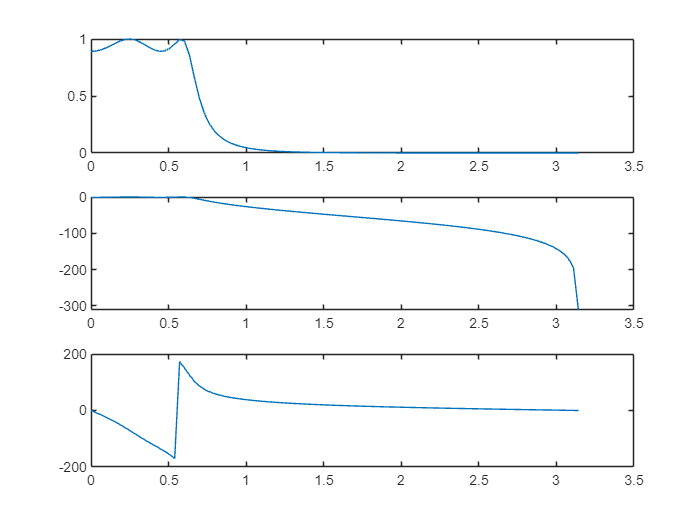

%设计模拟滤波器：
[B,A] = cheby1(N,Ap,wp,"low","s");
% 采用双线性变换法设计：
[Dz,Cz] = bilinear(B,A,fs);
% 画幅频、相频图：
W = linspace(0,pi); 
H = freqz(Dz,Cz,W);
mag = abs(H)/abs(H(1));
dbmag = 20*log10(mag);
phase = angle(H); 
degphase = phase*180/pi; 
subplot(3,1,1), plot(W,abs(H));
subplot(3,1,2), plot(W,dbmag);
subplot(3,1,3), plot(W,degphase);